addpath('D:\D\Alp\Master ODTÜ\Thesis\DOA\Codes\Direction-of-Arrival\Deep-Learning Basics on MATLAB\Custom Layers');

# Create Deep Learning Network Architecture

Script for creating the layers for a deep learning network with the following properties:

Run the script to create the layers in the workspace variable `lgraph`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 26-Apr-2024 20:55:38

## Create Layer Graph

Create the layer graph variable to contain the network layers.

lgraph = layerGraph();

## Add Layer Branches

Add the branches of the network to the layer graph. Each branch is a linear array of layers.

tempLayers = [
    imageInputLayer([8 8 1], "Name", "imageinput", "Normalization", "none")
    convolution2dLayer([4 4],10,"Name","conv")
    reluLayer("Name","relu")
    convolution2dLayer([3 3],5,"Name","conv_1")
    reluLayer("Name","relu_1")
    flattenLayer("Name","flatten")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    imageInputLayer([8 8 1], "Name", "imageinput_1", "Normalization", "none")
    convolution2dLayer([4 4],10,"Name","conv_2")
    reluLayer("Name","relu_2")
    convolution2dLayer([3 3],5,"Name","conv_3")
    reluLayer("Name","relu_3")
    flattenLayer("Name","flatten_1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(2,"Name","depthcat")
    fullyConnectedLayer(60, "Name", "fully_connected")
    reluLayer("Name","relu_4")
    SpatialToChannelBroadcastLayer('Spatial Dimension Adder')
    convolution2dLayer([15 1],3,"Name","conv1d","Padding","same")
    reluLayer("Name","relu_5")
    convolution2dLayer([5 1],1,"Name","conv1d_1","Padding","same")
    % flattenLayer("Name", "flatten_2")
    SSSpatialToChannelBroadcastLayer('Spatial Dimension Remover')
    sigmoidLayer("Name","sigmoid")
    regressionLayer("Name","regressionoutput")];
lgraph = addLayers(lgraph,tempLayers);

% clean up helper variable
clear tempLayers;

## Connect Layer Branches

Connect all the branches of the network to create the network graph.

lgraph = connectLayers(lgraph,"flatten","depthcat/in1");
lgraph = connectLayers(lgraph,"flatten_1","depthcat/in2");

## Plot Layers

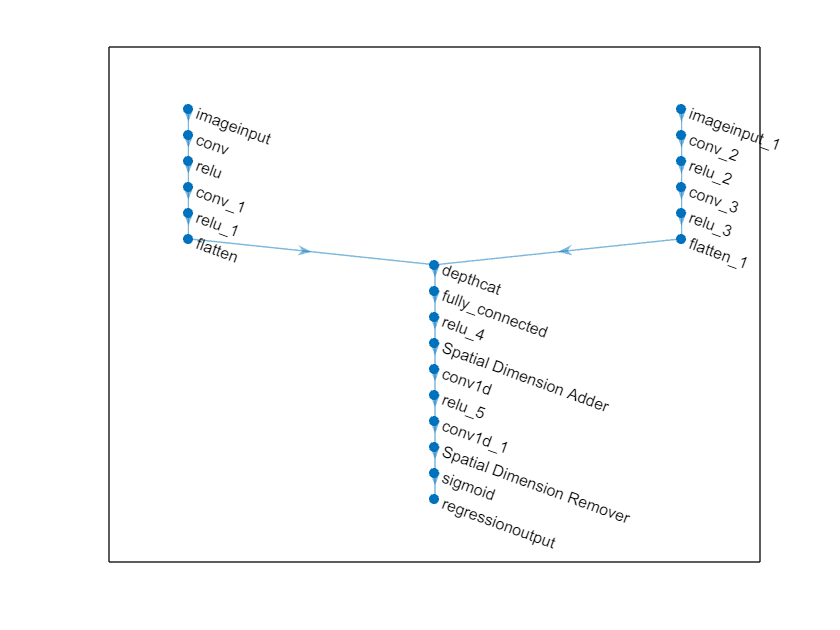

plot(lgraph);